## param initialize

dt = 0.002;

## model initialize

% A = [
%          0    1.0000         0         0         0         0
%   206.8934         0         0         0    0.5911         0
%          0         0         0    1.0000         0         0
%     8.5639         0         0         0    0.1195         0
%          0         0         0         0         0    1.0000
%     8.5652         0         0         0    9.9310         0];
% B = [
%          0         0
%   -19.5415    8.0117
%          0         0
%    -0.2400    0.3828
%          0         0
%    -0.2401    5.6695];
A = [0 1;1 0];
B = [0;1];
c_ss = ss(A,B,eye(size(A,1)),zeros(size(B)));
d_ss = c2d(c_ss,dt);
d_ss.A

ans =     1.0000    0.0020
    0.0020    1.0000


d_ss.B

ans =     0.0000
    0.0020


A_disc = expm(A*dt)

A_disc =     1.0000    0.0020
    0.0020    1.0000


% syms x
% B_disc = double(subs(int(expm(A*x),0,dt)*B))
% d_ss.B-B_disc
integral_N = 100;
x = 0:dt/integral_N:dt;
B_disc = zeros(size(B));
for i = 2:integral_N
    a = expm(A*x(i))*B;
    b = expm(A*x(i-1))*B;
    B_disc = B_disc + (a+b)*dt/integral_N/2;
end
B_disc

B_disc =     0.0000
    0.0020


d_ss.B-B_disc

ans = 	1.0e+-4 *

    0.0004
    0.2000


## lqr calculate

% Q_lqr = 1.3*diag([500 10 100 150 4000 30]);
% R_lqr = diag([1 0.25]);

Q_lqr = diag([1 1]);
R_lqr = 1e-3;

K_lqr = lqrd(A,B,Q_lqr,R_lqr,dt)

K_lqr =    31.6327   31.6327


% eig(A_disc-B_disc*K_mpc)

## mpc calculate

% Q_mpc = 1.3*diag([500 10 100 150 4000 30]);
% P_mpc = Q_mpc;
% R_mpc = diag([1 0.25]);

Q_mpc = diag([1 1]);
P_mpc = Q_mpc;
R_mpc = 1e-3;

N_mpc = 500;
F = F_cal(A_disc,N_mpc);
Phi = Phi_cal(A_disc,B_disc,N_mpc);
Q_bar = Q_bar_cal(Q_mpc,P_mpc,N_mpc);
R_bar = R_bar_cal(R_mpc,N_mpc);
p = size(B,2);
FdbMat_mpc = [eye(p),zeros(p,p*(N_mpc-1))]/(Phi'*Q_bar*Phi+R_bar)*Phi'*Q_bar;
K_mpc = FdbMat_mpc*F

K_mpc =    23.9245   31.3966


eig(A_disc-B_disc*K_mpc)

ans =     0.9985
    0.9393


t_end = 20;
t = 0:dt:t_end;
N = length(t);

Tracking = 1;
x_ref = zeros(size(A,1),N);
X_ref = zeros(size(A,1)*N_mpc,1);

u_lqr = zeros(size(B,2),N);
x_lqr = zeros(size(A,1),N);
x_lqr(:,1) = [1;0];

u_mpc = zeros(size(B,2),N);
x_mpc = zeros(size(A,1),N);
x_mpc(:,1) = [1;0];

for k = 2:N
    x_ref(:,k) = [sin(k*dt);0]*Tracking;

    u_lqr(k) = K_lqr*(x_ref(:,k)-x_lqr(:,k-1));
    x_lqr(:,k) = A_disc*x_lqr(:,k-1) + B_disc*u_lqr(k);

    for i = 1:N_mpc
        X_ref(i:i+size(A,1)-1,1) = [sin((k+i-1)*dt);0]*Tracking;
    end
    u_mpc(k) = FdbMat_mpc*(X_ref-F*x_mpc(:,k-1));
    x_mpc(:,k) = A_disc*x_mpc(:,k-1) + B_disc*u_mpc(k);
end

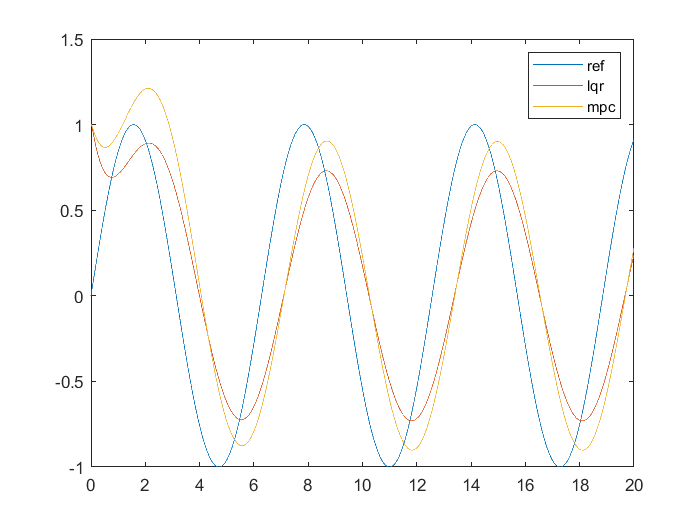

plot(t,x_ref(1,:),t,x_lqr(1,:),t,x_mpc(1,:));
legend('ref','lqr','mpc')

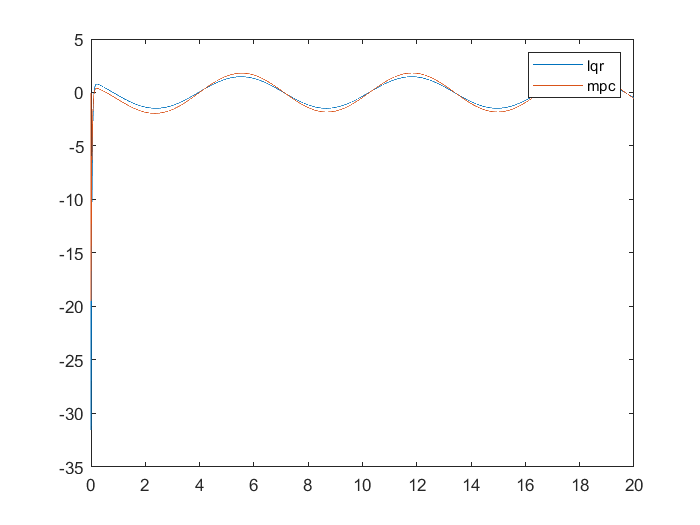

plot(t,u_lqr,t,u_mpc)
legend('lqr','mpc')

%plot(t,x_ref(2,:),t,x_lqr(2,:));

function F = F_cal(A, N)
A = sparse(A);
F = A;
temp = A;
if N > 1
    for i = 2:N
        temp = temp * A;
        %F = [F; F(i-size(A,1)+1:i,:) * A];
        F = [F; temp];
        %F = [F;A^i];
    end
end
end

function Phi = Phi_cal(A, B, N)
n = size(A,1);
p = size(B,2);
A = sparse(A);
B = sparse(B);
Phi = zeros(N*n,N*p);
Phi(1:n,:) = [B,zeros(n,p*(N-1))];
temp = A;
for i = 1:N-1
    rows = i*n+(1:n);
    %Phi(rows,:) = [A^i*B,Phi(rows-n,1:end-p)];
    Phi(rows,:) = [temp*B,Phi(rows-n,1:end-p)];
    temp = temp * A;
end
end

function Q_bar = Q_bar_cal(Q, P, N)
Q = sparse(Q);
P = sparse(P);
Q_tmp = kron(eye(N-1),Q);
Q_bar = blkdiag(Q_tmp,P);
end

function R_bar = R_bar_cal(R, N)
R = sparse(R);
R_bar = kron(eye(N),R);
end